%% Detecting and counting moving objects in video
% Copyright 2014 The MathWorks, Inc.
%% Clear Workspace
clear all;
close all
clc;
%% Read Video
videoReader = vision.VideoFileReader('Fish_Tank_E.mp4');  
%% Create Video Player
videoPlayer = vision.VideoPlayer;

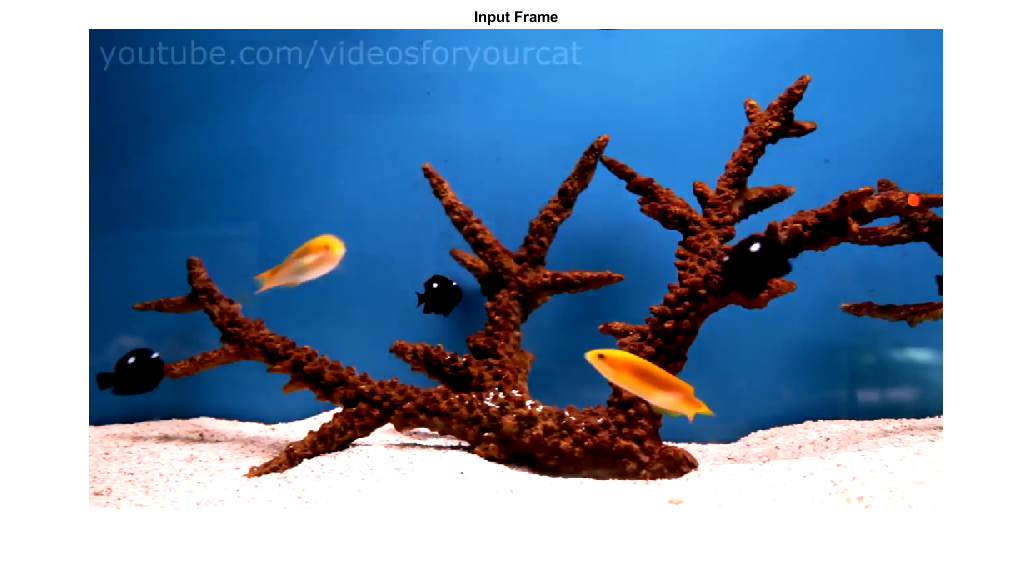

fgPlayer = vision.VideoPlayer;
%% Create Foreground Detector  (Background Subtraction)
foregroundDetector = vision.ForegroundDetector('NumGaussians', 25,'NumTrainingFrames', 50);
%% Run on first 75 frames to learn background
for i = 1:75
    videoFrame = step(videoReader);
    foreground = step(foregroundDetector,videoFrame);
end
% display 75th frame and foreground image
figure;
imshow(videoFrame);
title('Input Frame');

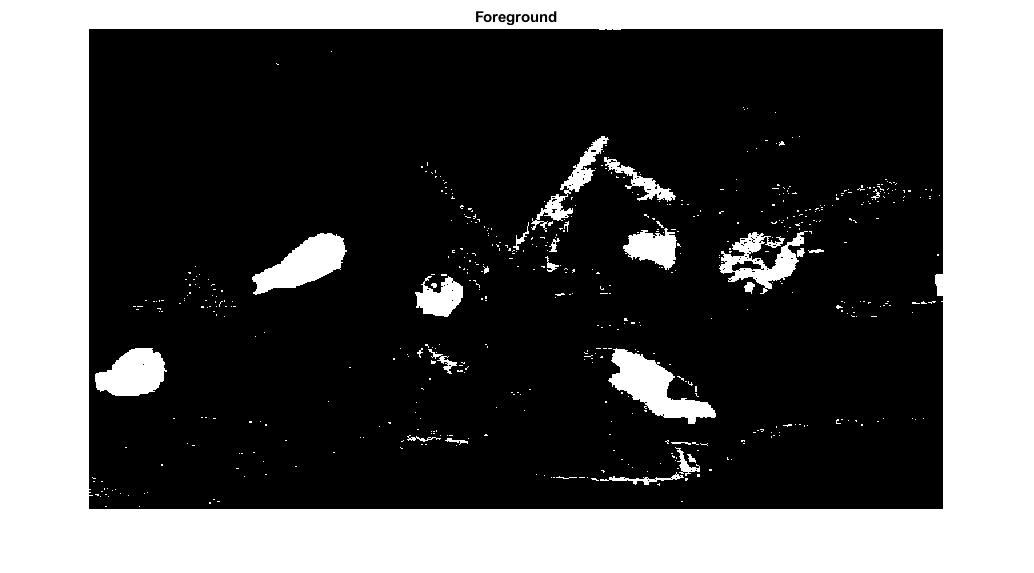

figure;
imshow(foreground);
title('Foreground');

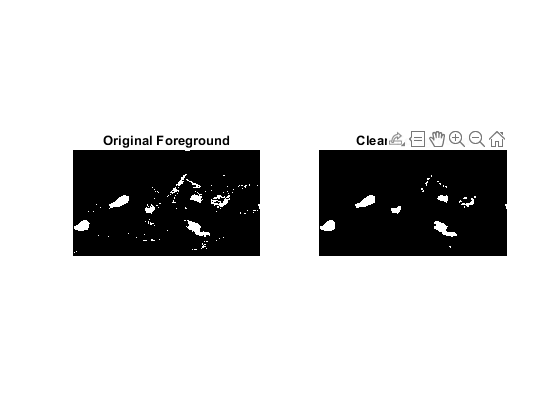

%% Perform morphology to clean up foreground 
cleanForeground = imopen(foreground, strel('Disk',5));
figure;
% Display original foreground
subplot(1,2,1);imshow(foreground);title('Original Foreground');
% Display foreground after morphology
subplot(1,2,2);imshow(cleanForeground);title('Clean Foreground');
%% Create blob analysis object 
%Blob analysis object further filters the detected foreground by rejecting blobs which contain fewer
% than 150 pixels.
blobAnalysis = vision.BlobAnalysis('BoundingBoxOutputPort', true, ...
    'AreaOutputPort', false, 'CentroidOutputPort', false, ...
    'MinimumBlobArea', 150);
%% Loop through video
while  ~isDone(videoReader)
    %Get the next frame
    videoFrame = step(videoReader);
    
    %Detect foreground pixels
    foreground = step(foregroundDetector,videoFrame);
    % Perform morphological filtering
    cleanForeground = imopen(foreground, strel('Disk',5));
            
    % Detect the connected components with the specified minimum area, and
    % compute their bounding boxes
    bbox = step(blobAnalysis, cleanForeground);
    % Draw bounding boxes around the detected cars
    result = insertShape(videoFrame, 'Rectangle', bbox, 'Color', 'green');
    % Display the number of cars found in the video frame
    numCars = size(bbox, 1);
    text = sprintf('Detected Vehicles = %d',numCars);
    result = insertText(result, [10 10], numCars, 'BoxOpacity', 1, ...
        'FontSize', 14);
    % Display output 
    step(videoPlayer, result);
    step(fgPlayer,cleanForeground);
    
end

%% release video reader and writer
release(videoPlayer);
release(videoReader);
release(fgPlayer);
delete(videoPlayer); % delete will cause the viewer to close
delete(fgPlayer);